## RRT 

Motion Planning on Matlab Automated Parking Valet Map

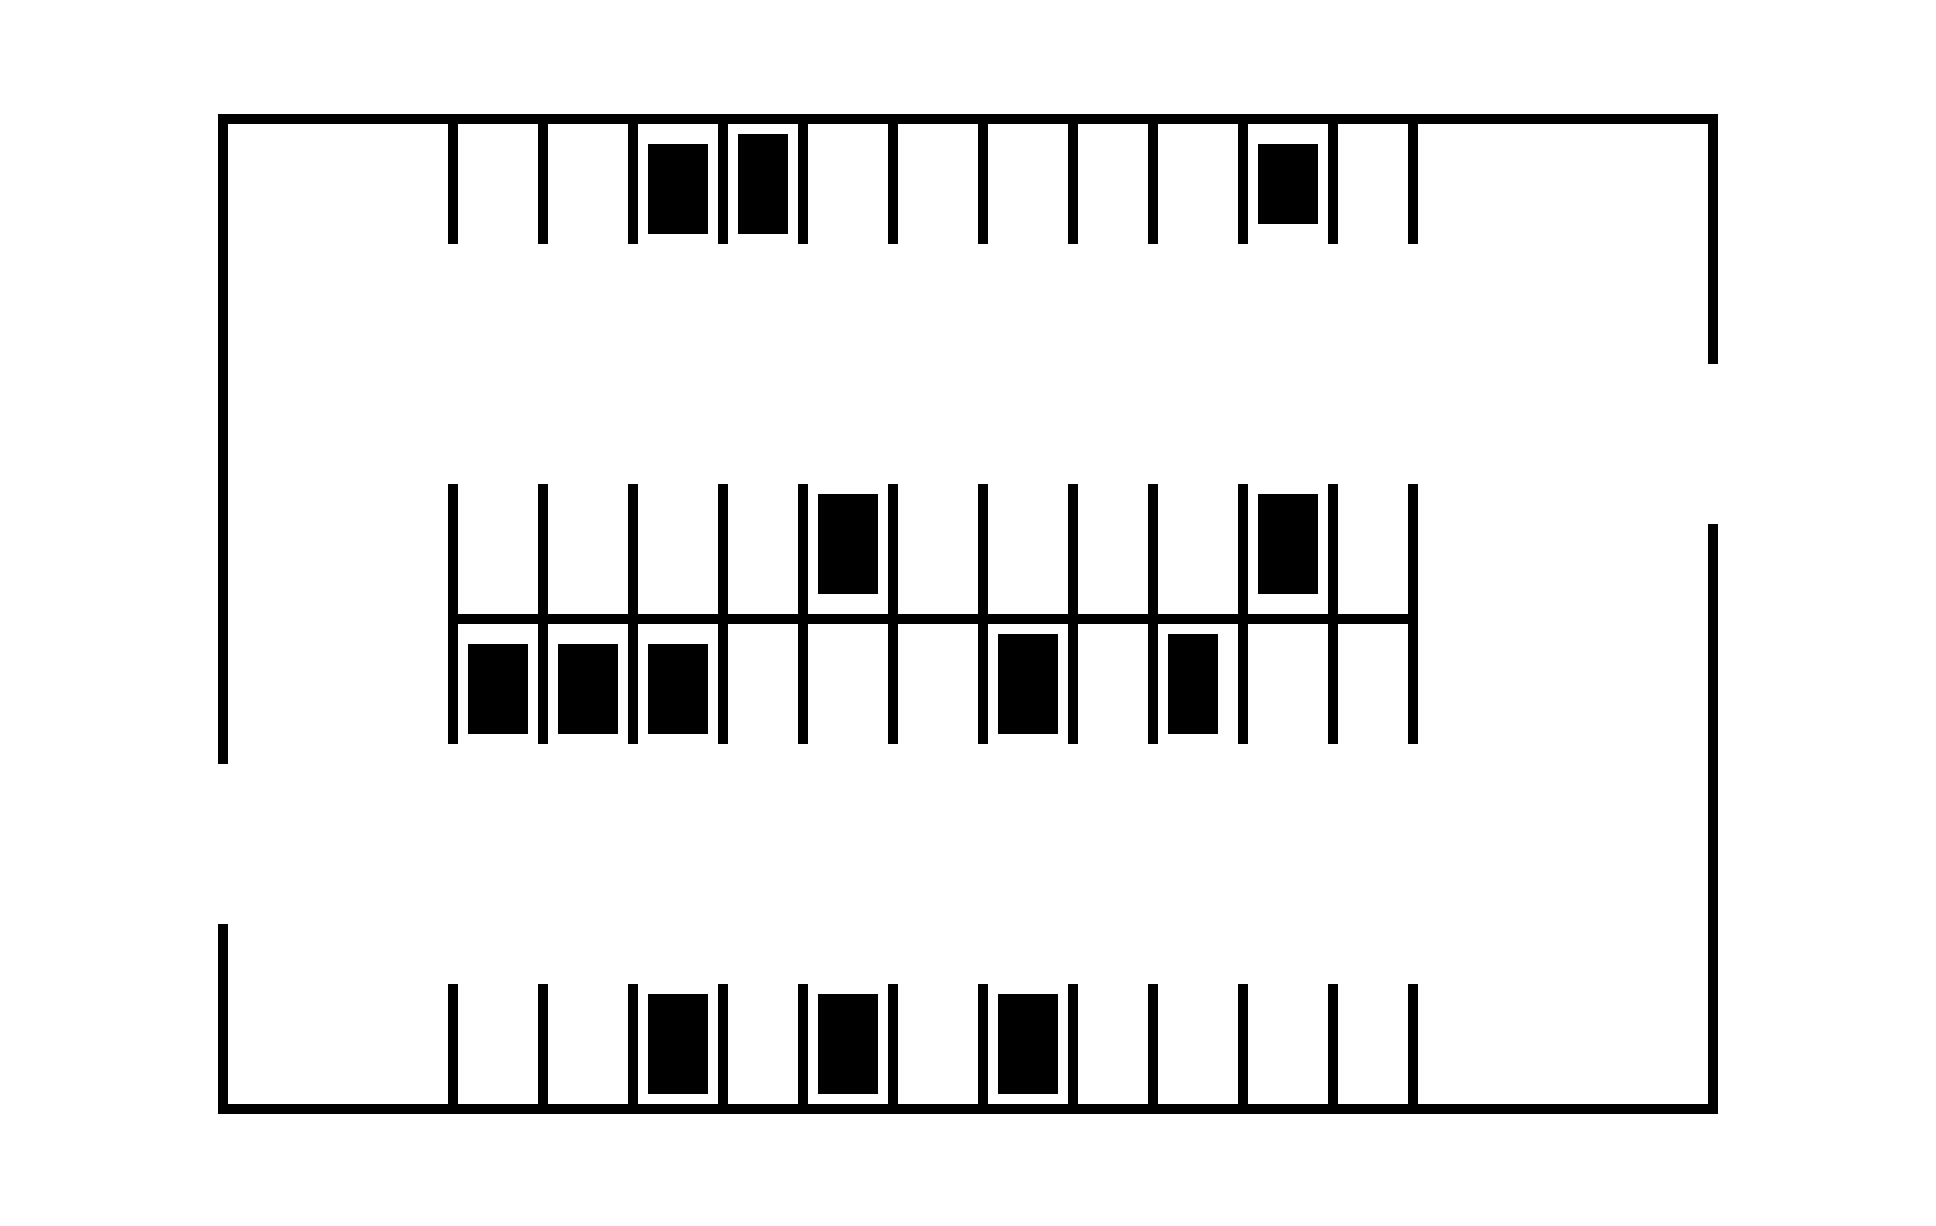

ws = load('input_variables_from_matlab_parking_example.mat');
costmap_image = ws.combinedMap;
figure;
costmap_image = mat2gray(~costmap_image(:,:));
imshow(costmap_image);
truesize([500 750]);
hold on;

% Matlab parking valet inputs
costmap = ws.combinedMap;
minTurning = 4;
dis = 10;
routePlan = ws.routePlan;
startPos = [5 75 0];
% 0 = right, up = -pi/2, left = pi/2
% goalPoses = {[63 7 -pi/2]};
%intermediate points
% goalPoses = {[80 75 0],[140 75 -pi/2],[140 20 -pi/2], [75 20 pi/2], [63 7 -pi/2]};
goalPoses = {[80 75 0] ,[115 55 -pi/2]};
iterations = 2000;
tolerance = 3;

fasfdsf
fasfdsf
fasfdsf
fasfdsf


fasfdsf


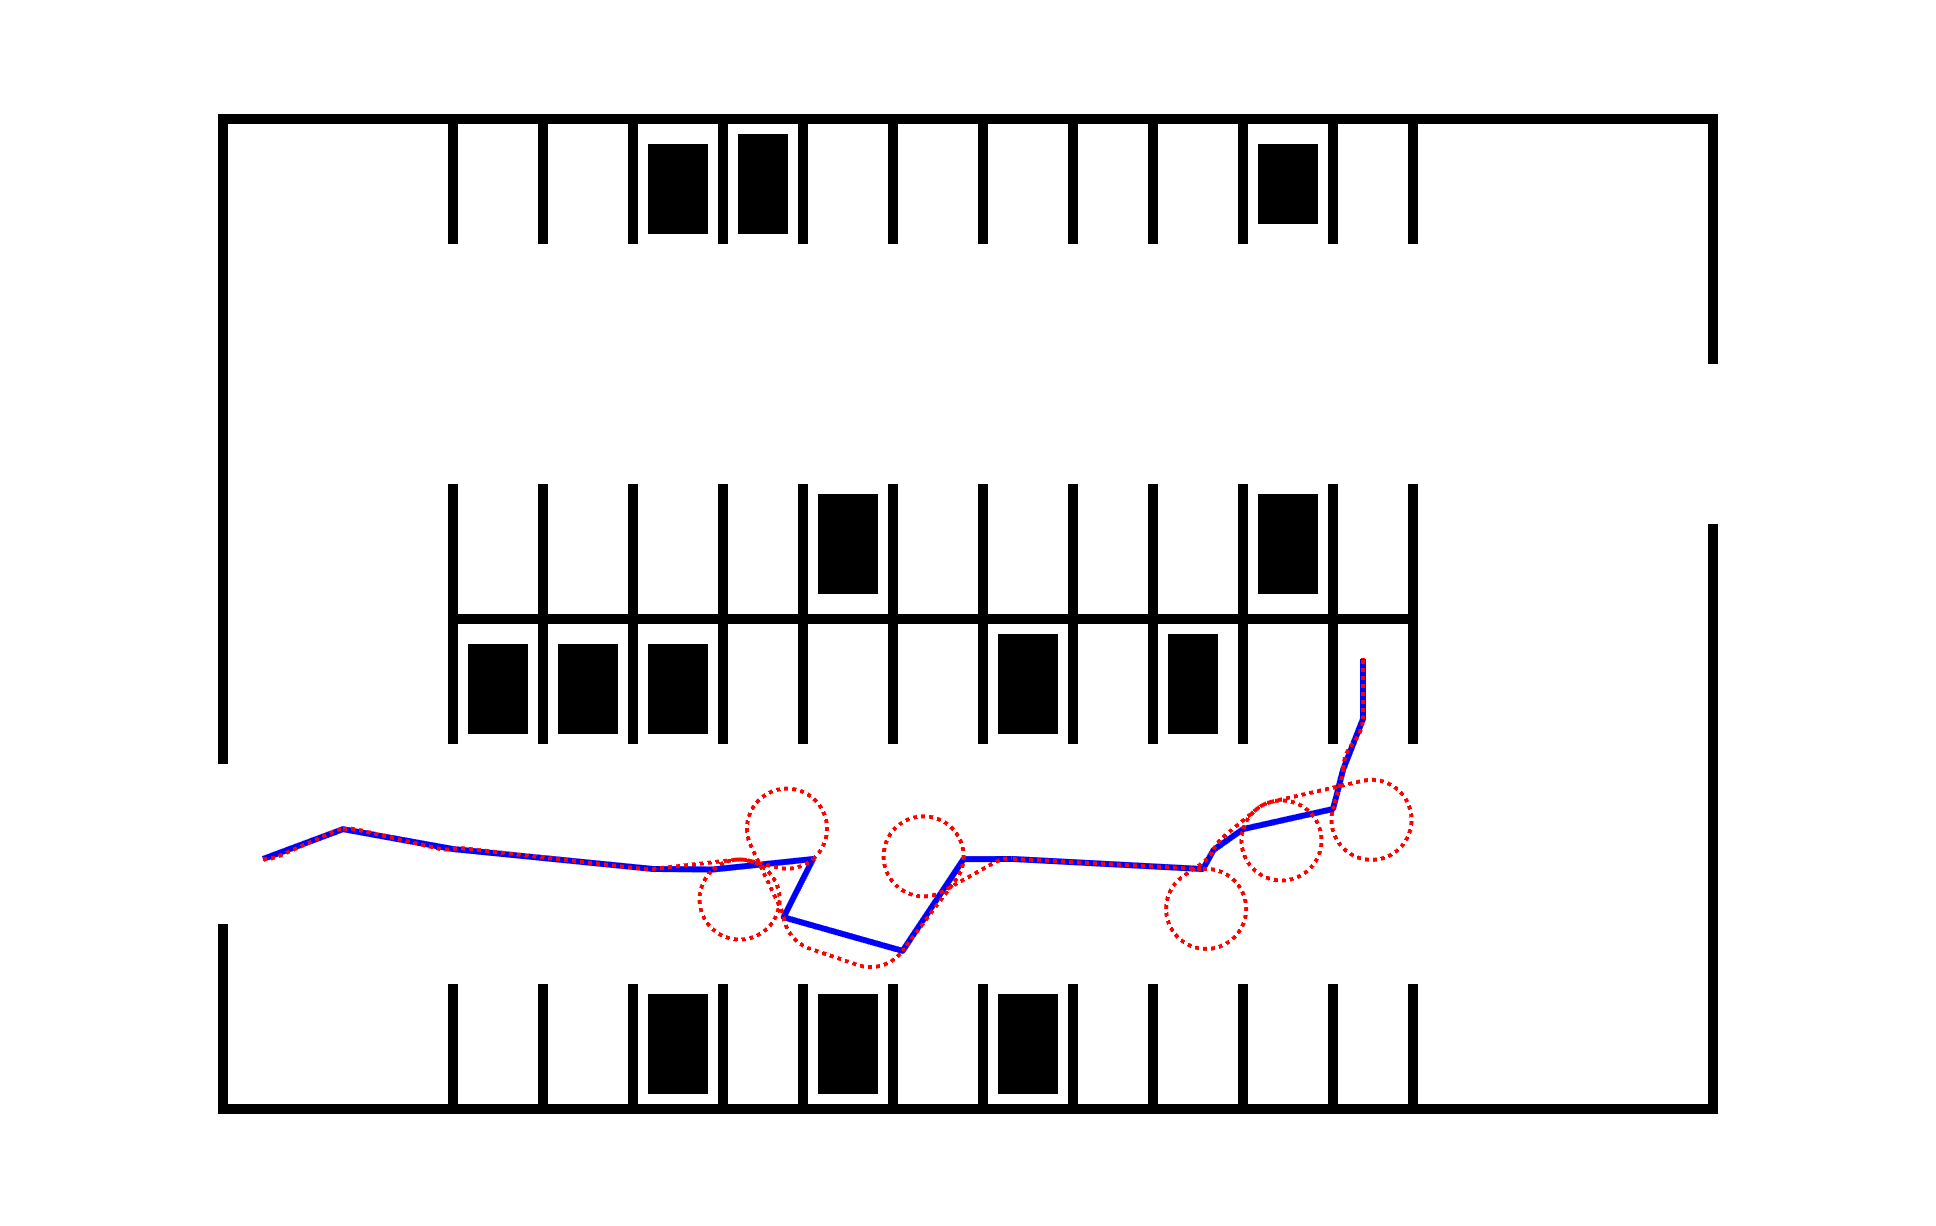

i = 1;
while i <= length(goalPoses)
    tree = rrt(costmap', iterations, startPos, goalPoses{i}, minTurning, dis, tolerance);
    disp("fasfdsf");
    [path, dubinsSegments, Tree]= run(tree);
    if (isempty(path) || length(path) <= 1)
        continue;
    end
    for j = 1:length(path)
        p = plot(path(:,1), path(:,2), 'b');
        p(1).LineWidth = 3;
    end
    for jj = 1:length(dubinsSegments)
        dubinsPath = dubinsSegments{jj};
        points = dubinsPath.PathPoses;
        p2 = plot(points(:, 1), points(:, 2), 'r'); 
        p2(1).LineStyle = ':';
        p2(1).LineWidth = 2;
    end
    startPos = goalPoses{i};
    i = i+1;
end